# main

## parameters

Ts = 0.01; % sampling time
N = 1000; % nr points on the trajectories
normalize_trajectories = false;
trajectory_scale = 1; % scaling to be applied to trajectories

## load trajectories

data_dir = 'data';
path_dirs = dir(fullfile(data_dir, 'path_*'));
path_dirs = path_dirs([path_dirs.isdir]);

paths = struct('name', {}, 'control', {}, 'smooth', {}, 'offset', ...
    {}, 'setpoint', {}, 'setpoint_angle', {}, 'img', {});

for i = 1:numel(path_dirs)
    folder_name = path_dirs(i).name;
    folder_path = fullfile(data_dir, folder_name);

    control_file = fullfile(folder_path, 'control_path.csv');
    smooth_file  = fullfile(folder_path, 'smooth_path.csv');
    img_file  = fullfile(folder_path, 'canvas.png');

    paths(i).name = folder_name;

    if isfile(control_file)
        % points
        paths(i).control = readmatrix(control_file);

        % offset
        paths(i).offset = paths(i).control(1, :);

        % setpoint
        paths(i).setpoint = paths(i).control(end-1, :);
        paths(i).setpoint_angle = paths(i).control(end, 1);

        % remove offset and setpoint
        paths(i).control = paths(i).control(2:end-2, :);
    else
        paths(i).control = [];
    end

    if isfile(smooth_file)
        paths(i).smooth = readmatrix(smooth_file);
    else
        paths(i).smooth = [];
    end

    if isfile(control_file)
        paths(i).img = imread(img_file);
    else
        paths(i).img = [];
    end
end

paths

paths = 1×7 struct array with fields:
    name
    control
    smooth
    offset
    setpoint
    setpoint_angle
    img


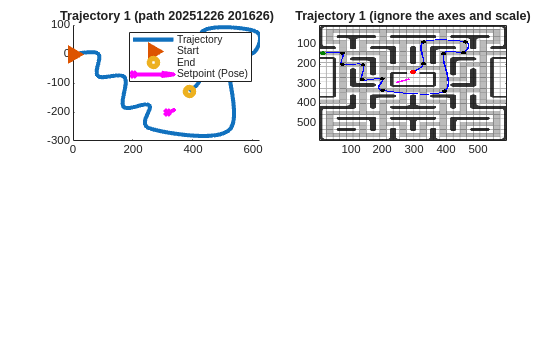

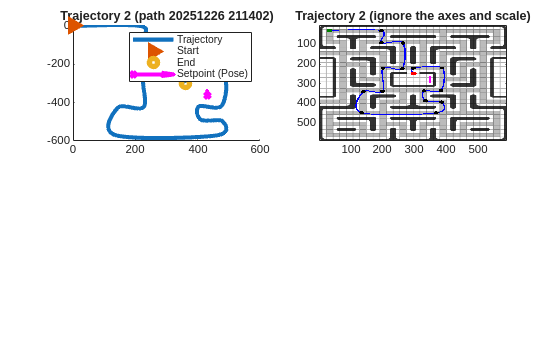

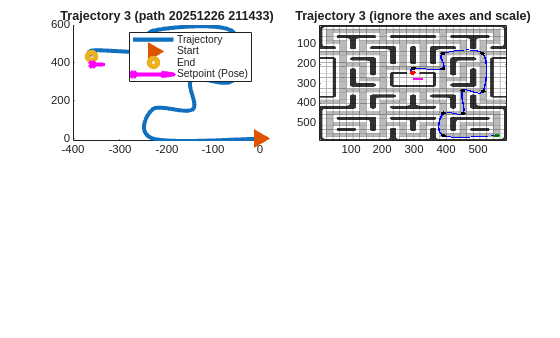

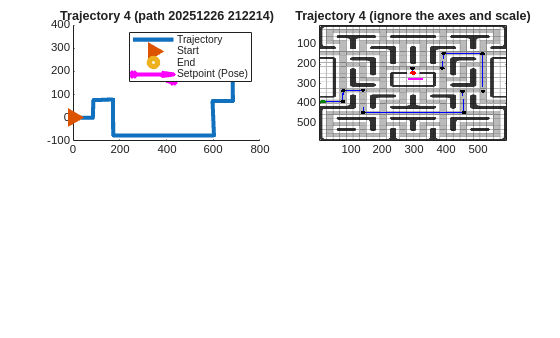

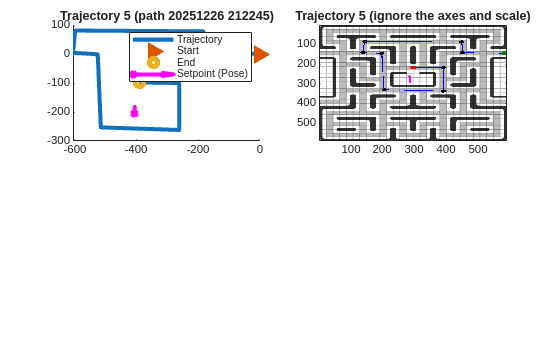

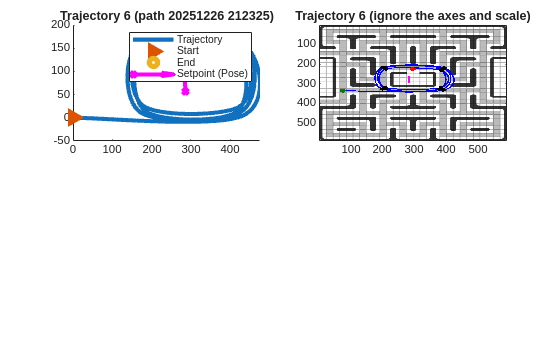

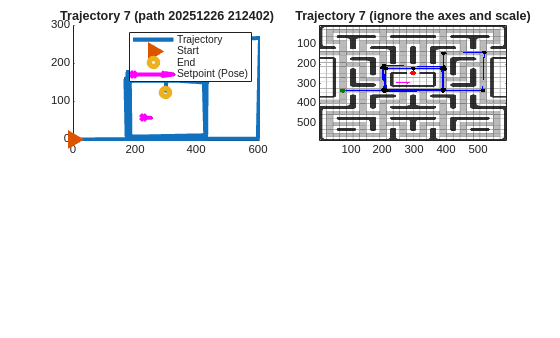

for i = 1:size(paths, 2)
    figure;
    subplot(2, 2, 1);
    hold on;
    x = paths(i).smooth(:, 1);
    y = paths(i).smooth(:, 2);
    plot(x, y, "LineWidth", 3.0, "DisplayName", "Trajectory");
    plot(0, 0, ">", "LineWidth", 4.0, "DisplayName", "Start");
    plot(x(end), y(end), "o", "LineWidth", 4.0, "DisplayName", "End");
    title("Trajectory " + i + " (" + strrep(paths(i).name, '_', ' ') + ")");
    quiver(paths(i).setpoint(1), paths(i).setpoint(2), 25*cos(paths(i).setpoint_angle), ...
        25*sin(paths(i).setpoint_angle), "Color", "Magenta", "DisplayName", "Setpoint (Pose)", ...
        "LineWidth", 3.0, "Marker", "x");
    hold off;
    legend();

    subplot(2, 2, 2);
    image(paths(i).img);
    title("Trajectory " + i + " (ignore the axes and scale)");
end

## process trajectories for simulation

unprocessed_trajectories = {};
for i = 1:numel(paths)
    unprocessed_trajectories{i} = paths(i).smooth;
end
trajectories = process_trajectories(unprocessed_trajectories, Ts, N, normalize_trajectories, trajectory_scale)


trajectories =

  dictionary (string ⟼ struct) with 7 entries:

    "trajectory1" ⟼ 1×1 struct
    "trajectory2" ⟼ 1×1 struct
    "trajectory3" ⟼ 1×1 struct
    "trajectory4" ⟼ 1×1 struct
    "trajectory5" ⟼ 1×1 struct
    "trajectory6" ⟼ 1×1 struct
    "trajectory7" ⟼ 1×1 struct



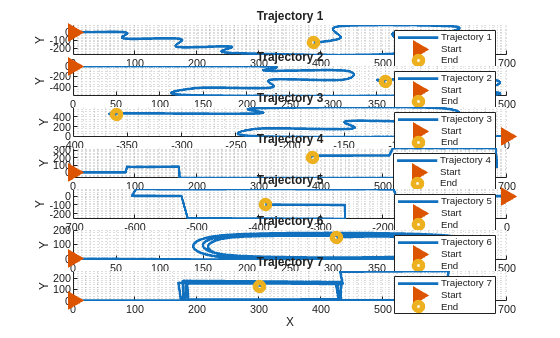

% plot
figure;
len = 0;
x_range = 0;
y_range = 0;
nr_trajectories = numel(unprocessed_trajectories);
for i = 1:nr_trajectories
    xd_ts = trajectories("trajectory"+i).xd_ts;
    yd_ts = trajectories("trajectory"+i).yd_ts;
    len = numel(xd_ts.Data);

    subplot(nr_trajectories, 1, i);
    hold on;
    plot(xd_ts.Data, yd_ts.Data, "LineWidth", 2.0, "DisplayName", "Trajectory "+i);
    plot(0, 0, ">", "LineWidth", 4.0, "DisplayName", "Start");
    plot(xd_ts.Data(end), yd_ts.Data(end), "o", "LineWidth", 4.0, "DisplayName", "End");
    hold off;

    grid minor;
    title("Trajectory " + i);
    xlabel("X");
    ylabel("Y");

    legend();
end

## sim

sim_trajectory_id = 6

sim_trajectory_id = 6

simulation_duration = Ts * N

simulation_duration = 10